clear; close all;


% First, setup the system, see fmcwDemo.m for more details

% Carrier frequency
fc = 10e9;
lambda = physconst("LightSpeed")/fc;

% Put some requirements on the system
maxRange = 10;
rangeResolution = 1/3;
maxSpeed = 5;
speedResolution = 1/2;

% Determine some parameter values
rampbandwidth = ceil(rangeres2bw(rangeResolution)/1e6)*1e6;
fmaxdop = speed2dop(2*maxSpeed,lambda);
prf = 2*fmaxdop;
nPulses = ceil(2*maxSpeed/speedResolution);
tpulse = ceil((1/prf)*1e3)*1e-3;
tsweep = getFMCWSweepTime(tpulse,tpulse);
sweepslope = rampbandwidth / tsweep;
fmaxbeat = sweepslope * range2time(maxRange);
fs = max(ceil(2*fmaxbeat),520834);

%% Create arrays for radar display plot

% Additional parameters
Dmax = 0.115;                       % Maximum linear dimension [m]
FarField = 2*Dmax^2/lambda;         % Far field range [m]
b_theta = 26;                       % Elevation beamwidth [degrees]
b_phi = 13;                         % Azimuth beamwidth [degrees]
disp_limit = maxRange + 2*rangeResolution;

% Azimuth steering angles
n = floor(90/b_phi);
az_steer = linspace(-n*b_phi,n*b_phi,2*n+1);

% Azimuth cell angles
az_cell = linspace(-n*b_phi-b_phi/2,n*b_phi+b_phi/2,2*(n+1));

% Range cell array
n = floor(maxRange/rangeResolution);
range1 = linspace(0,maxRange+rangeResolution,n+2);
range = [];
for i = 1:n+2
    if range1(i) > FarField
        range = cat(2,range,range1(i));
    end
end

% Polygon arrays
az = [-b_phi/2, b_phi/2];
az = az*pi/180;
theta = az + pi/2;
x_poly = [];
y_poly = [];
for i = 1:length(range)-1
    r = [range(i) range(i+1)];
    x1 = zeros(4,1);
    y1 = zeros(4,1);
    [x1(1), y1(1)] = pol2cart(theta(1), r(1));
    [x1(2), y1(2)] = pol2cart(theta(1), r(2));
    [x1(3), y1(3)] = pol2cart(theta(2), r(2));
    [x1(4), y1(4)] = pol2cart(theta(2), r(1));
    x_poly = cat(2,x_poly,x1);
    y_poly = cat(2,y_poly,y1);
end


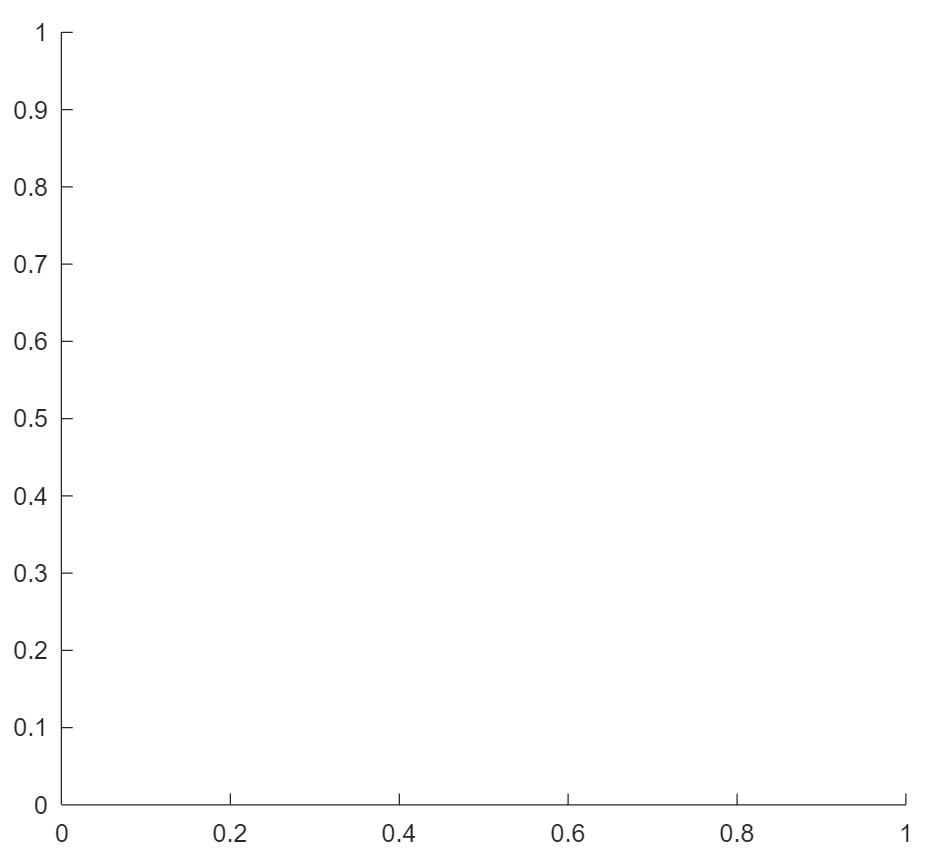

% Import data and calculate/plot ZDR

% Upload folder
folder = "C:\Users\forev\Documents\MATLAB\RadarChallenge\outputs\data";
dir1 = dir(folder);

% Specify start and end time for vertical collection
v_start =   '20240410T223737_RadarChallenge_data.mat';
v_stop =    '20240410T223805_RadarChallenge_data.mat';
v_start_time = v_start(10:15);
v_stop_time = v_stop(10:15);
v_start_time = str2double(v_start_time);
v_stop_time = str2double(v_stop_time);

% Specify start and end time for horizontal collection
h_start =   '20240410T222733_RadarChallenge_data.mat';
h_stop =    '20240410T222754_RadarChallenge_data.mat';
h_start_time = h_start(10:15);
h_stop_time = h_stop(10:15);
h_start_time = str2double(h_start_time);
h_stop_time = str2double(h_stop_time);

% Create data arrays for captures between start and end times
v_data_array = [];
h_data_array = [];
for i=3:length(dir1)
    file_str = dir1(i).name;
    file_time = str2double(file_str(10:15));
    
    % Vertical data
    if (file_time >= v_start_time) && (file_time <= v_stop_time)
        data_temp = importdata(folder + "\" + file_str);
        v_data_array = cat(1,v_data_array,data_temp);
    end

    % Horizontal data
    if (file_time >= h_start_time) && (file_time <= h_stop_time)
        data_temp = importdata(folder + "\" + file_str);
        h_data_array = cat(1,h_data_array,data_temp);
    end

end

% Average the captures for vertical
dim_v = size(v_data_array);
v_data = zeros(1,dim_v(2));
for a = 1:dim_v(2)
    sum = 0;
    for b = 1:dim_v(1)
        sum = sum + v_data_array(b,a);
    end
    v_data(a) = sum/dim_v(1);
end

% Average the captures for horizontal
dim_h = size(h_data_array);
h_data = zeros(1,dim_h(2));
for a = 1:dim_h(2)
    sum = 0;
    for b = 1:dim_h(1)
        sum = sum + h_data_array(b,a);
    end
    h_data(a) = sum/dim_h(1);
end

% Find ZDR = Zh - Zv
ZDR = zeros(1,length(h_data));
for a = 1:length(h_data)
    ZDR(a) = h_data(a) - v_data(a);
end


% Truncate from far field to max range
n = length(ZDR);
k = (n+1)/2;
n = floor(maxRange/rangeResolution)+1;
x1 = linspace(0,maxRange,n);
x = [];
for a=1:n
    if x1(a) > FarField
        x = cat(2,x,x1(a));
    end
end

% Plot horizontal reflectivity
figure('Units', 'normalized', 'Position', [0.25, 0.1, 0.5, 0.8])
plot_h = tiledlayout('flow','TileSpacing','tight','Padding','compact');
display_h = nexttile;

    % Radar display
patch(x_poly,y_poly,h_data,'Parent',display_h)

Error using patch
Vectors must be the same length.

daspect(display_h, [1 1 1]);
xlim(display_h, "manual"); ylim(display_h, "manual");
xlim(display_h,[-disp_limit,disp_limit]); ylim(display_h,[0,disp_limit]);
clim(display_h,[0 80]);
display_h_title = "Radar Display";
title(display_h, display_h_title);
xlabel(display_h, 'x [m]')
ylabel(display_h, 'y [m]')
colormap(display_h, "turbo");
cb = colorbar(display_h,'eastoutside');
cb.Label.String = 'Horizontal Reflectivity [dBZ h]';
drawnow;
    % A-scope
Ascope_h = nexttile;
plot(x,h_data,'Parent',Ascope_h)
pbaspect(Ascope_h, [2 1 1]);
xlim(Ascope_h, "manual"); ylim(Ascope_h, "manual");
xlim(Ascope_h,[0,maxRange]); ylim(Ascope_h,[0,80]);
Ascope_h_title = "A-Scope";
title(Ascope_h, Ascope_h_title);
xlabel(Ascope_h, 'Range [m]')
ylabel(Ascope_h, 'Horizontal Reflectivity [dBZ h]')
drawnow;

% Plot vertical reflectivity
figure('Units', 'normalized', 'Position', [0.25, 0.1, 0.5, 0.8])
plot_v = tiledlayout('flow','TileSpacing','tight','Padding','compact');
display_v = nexttile;
    % Radar display
patch(x_poly,y_poly,v_data,'Parent',display_v)
daspect(display_v, [1 1 1]);
xlim(display_v, "manual"); ylim(display_v, "manual");
xlim(display_v,[-disp_limit,disp_limit]); ylim(display_v,[0,disp_limit]);
clim(display_v,[0 80]);
display_v_title = "Radar Display";
title(display_v, display_v_title);
xlabel(display_v, 'x [m]')
ylabel(display_v, 'y [m]')
colormap(display_v, "turbo");
cb = colorbar(display_v,'eastoutside');
cb.Label.String = 'Vertical Reflectivity [dBZ h]';
drawnow;
    % A-scope
Ascope_v = nexttile;
plot(x,v_data,'Parent',Ascope_v)
pbaspect(Ascope_v, [2 1 1]);
xlim(Ascope_v, "manual"); ylim(Ascope_v, "manual");
xlim(Ascope_v,[0,maxRange]); ylim(Ascope_v,[0,80]);
Ascope_v_title = "A-Scope";
title(Ascope_v, Ascope_v_title);
xlabel(Ascope_v, 'Range [m]')
ylabel(Ascope_v, 'Vertical Reflectivity [dBZ h]')
drawnow;

% Plot Differential reflectivity
figure('Units', 'normalized', 'Position', [0.25, 0.1, 0.5, 0.8])
plots = tiledlayout('flow','TileSpacing','tight','Padding','compact');
display_sub = nexttile;
    % Radar display
patch(x_poly,y_poly,ZDR,'Parent',display_sub)
daspect(display_sub, [1 1 1]);
xlim(display_sub, "manual"); ylim(display_sub, "manual");
xlim(display_sub,[-disp_limit,disp_limit]); ylim(display_sub,[0,disp_limit]);
clim(display_sub,[-5 5]);
display_sub_title = "Radar Display";
title(display_sub, display_sub_title);
xlabel(display_sub, 'x [m]')
ylabel(display_sub, 'y [m]')
colormap(display_sub, "turbo");
cb = colorbar(display_sub,'eastoutside');
cb.Label.String = 'Differential Reflectivity [ZDR]';
drawnow;
    % A-scope
Ascope_sub = nexttile;
plot(x,ZDR,'Parent',Ascope_sub)
pbaspect(Ascope_sub, [2 1 1]);
xlim(Ascope_sub, "manual"); ylim(Ascope_sub, "manual");
xlim(Ascope_sub,[0,maxRange]); ylim(Ascope_sub,[-5,5]);
Ascope_sub_title = "A-Scope";
title(Ascope_sub, Ascope_sub_title);
xlabel(Ascope_sub, 'Range [m]')
ylabel(Ascope_sub, 'Differential Reflectivity [ZDR]')
drawnow;
